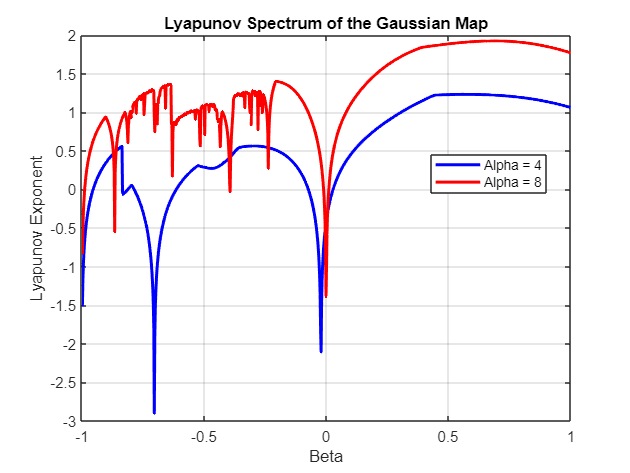

% Define parameters
alpha_values = [4, 8];
beta_values = linspace(-1, 1, 1000); % Values of Beta

% Initialize Lyapunov exponents array
lyapunov_exponents = zeros(length(alpha_values), length(beta_values));

for alpha_idx = 1:length(alpha_values)
    alpha = alpha_values(alpha_idx);

    for beta_idx = 1:length(beta_values)
        beta = beta_values(beta_idx);

        % Initialize variables
        x0_values = [0, -1];
        num_iterations = 1000;
        sum_log_derivative = 0;

        for x0 = x0_values
            x = x0;

            for n = 1:num_iterations
                % Gaussian map iteration
                
                x = exp(-alpha*x^2) + beta ;

                % Compute the derivative of the map
                map_derivative = -2 * alpha * x * exp(-x^2);

                % Update the sum of logarithmic derivatives
                sum_log_derivative = sum_log_derivative + log(abs(map_derivative));
            end
        end

        % Compute the average logarithmic derivative
        average_log_derivative = sum_log_derivative / (num_iterations * length(x0_values));

        % Store Lyapunov exponent
        lyapunov_exponents(alpha_idx, beta_idx) = average_log_derivative;
    end
end

% Plot the Lyapunov spectrum
figure;
plot(beta_values, lyapunov_exponents(1, :), 'b', 'LineWidth', 2, 'DisplayName', 'Alpha = 4');
hold on;
plot(beta_values, lyapunov_exponents(2, :), 'r', 'LineWidth', 2, 'DisplayName', 'Alpha = 8');
xlabel('Beta');
ylabel('Lyapunov Exponent');
title('Lyapunov Spectrum of the Gaussian Map');
legend('Location', 'best');
grid on;